## IMPORT LIBRARY

addpath('/Users/simone/Documents/MATLAB/R1/LIBRARY/')  
savepath /Users/simone/Documents/MATLAB/R1/LIBRARY/pathdef.m

# DIFFERENTIAL KINEMATIC	

differential kinematics gives the relationship between the joint velocities and the corresponding end-effector linear and angular velocity.

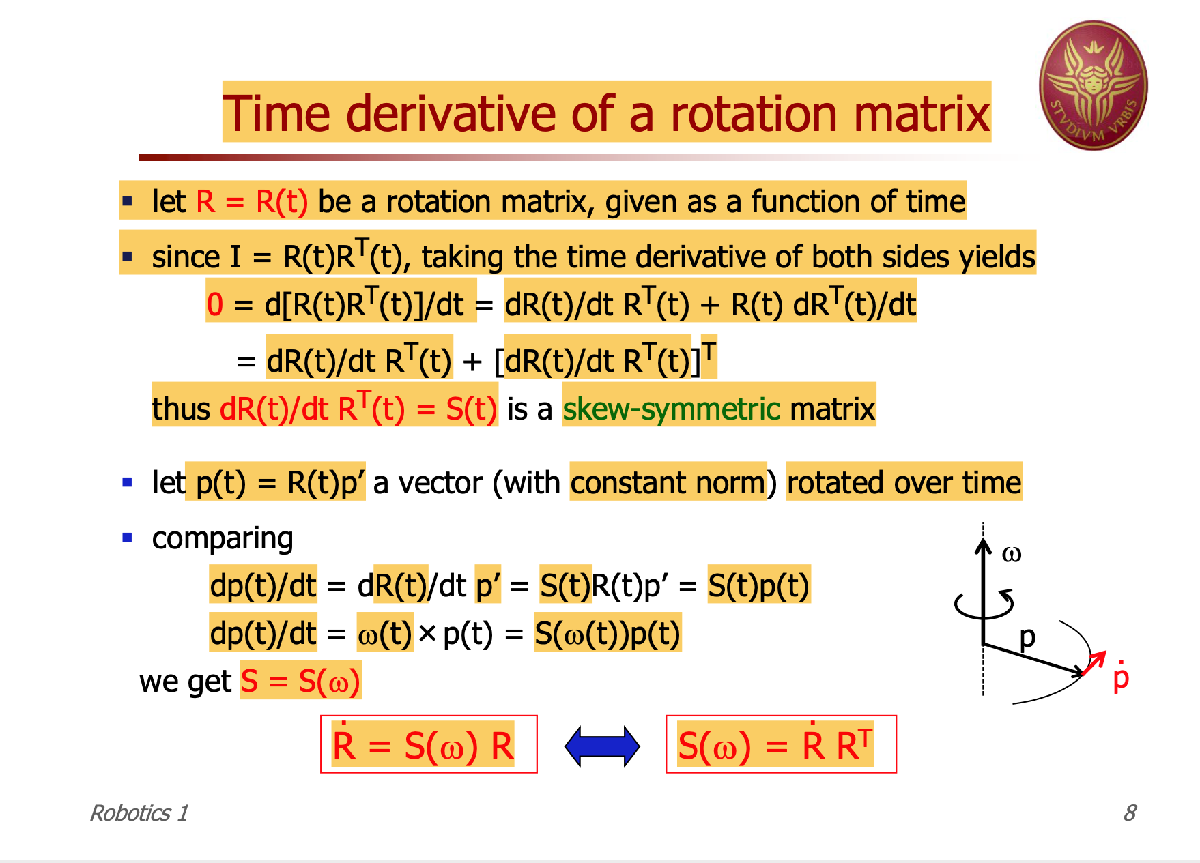

# TIME DERIVATIVE OF A ROTATION MATRIX

syms phi(t) t

assumeAlso(phi(t),'real')

[rx, ry, rz] = deal(phi(t), 0, 0);

R = SR_ROBO.R_x(rx) * SR_ROBO.R_y(ry) * SR_ROBO.R_z(rz)

$$R = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\varphi \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right)\\ 0 & \sin\left(\varphi \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right) \end{array}\right)$$


R_der = diff(R)

$$R\_der = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & -\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right) & -\cos\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\\ 0 & \cos\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right) & -\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right) \end{array}\right)$$


S_0_B = simplify(R_der * R')

$$S\_0\_B = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & -\frac{\partial }{\partial t}\varphi \left(t\right)\\ 0 & \frac{\partial }{\partial t}\varphi \left(t\right) & 0 \end{array}\right)$$


SR_ROBO.isSkew(S_0_B);

p = [0 0 1]';

p_dot = R_der * p;

# TIME DERIVATIVE OF RPY ANGLES AND $\omega$ 

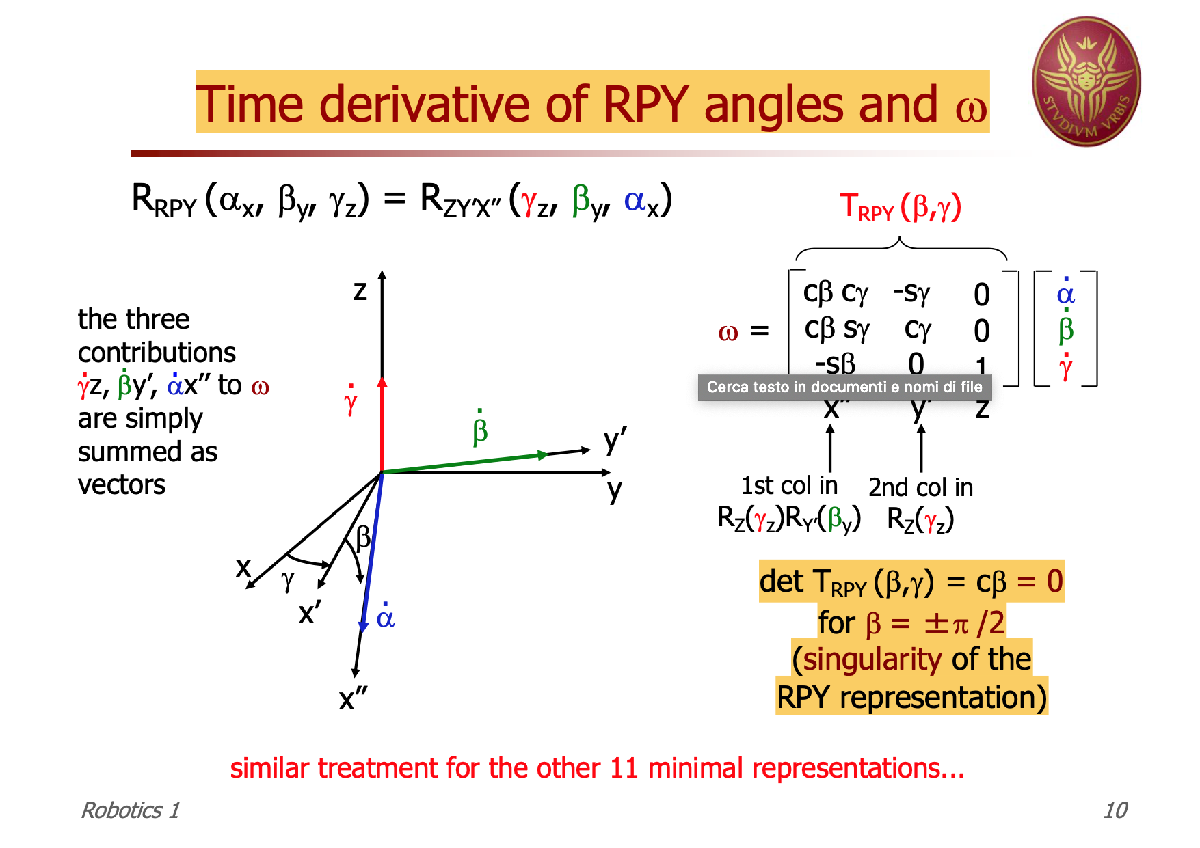

syms alpha(t) beta(t) gamma(t) t

assumeAlso(alpha(t),'real')

assumeAlso(beta(t),'real')

assumeAlso(gamma(t),'real')

% takes moving axis notation

[T,phi_dot] = SR_ROBO.getMappingT(alpha(t), beta(t), gamma(t),'rpy')

$$T = \left(\begin{array}{ccc} \cos\left(\beta \left(t\right)\right)\,\cos\left(\gamma \left(t\right)\right) & -\sin\left(\gamma \left(t\right)\right) & 0\\ \cos\left(\beta \left(t\right)\right)\,\sin\left(\gamma \left(t\right)\right) & \cos\left(\gamma \left(t\right)\right) & 0\\ -\sin\left(\beta \left(t\right)\right) & 0 & 1 \end{array}\right)$$

$$phi\_dot = \left(\begin{array}{c} \frac{\partial }{\partial t}\alpha \left(t\right)\\ \frac{\partial }{\partial t}\beta \left(t\right)\\ \frac{\partial }{\partial t}\gamma \left(t\right) \end{array}\right)$$


w = T * diff([alpha(t),beta(t),gamma(t)]).'

$$w = \left(\begin{array}{c} \cos\left(\beta \left(t\right)\right)\,\cos\left(\gamma \left(t\right)\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)-\sin\left(\gamma \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)\\ \cos\left(\gamma \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)+\cos\left(\beta \left(t\right)\right)\,\sin\left(\gamma \left(t\right)\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)\\ \frac{\partial }{\partial t}\gamma \left(t\right)-\sin\left(\beta \left(t\right)\right)\,\frac{\partial }{\partial t}\alpha \left(t\right) \end{array}\right)$$

# JACOBIAN

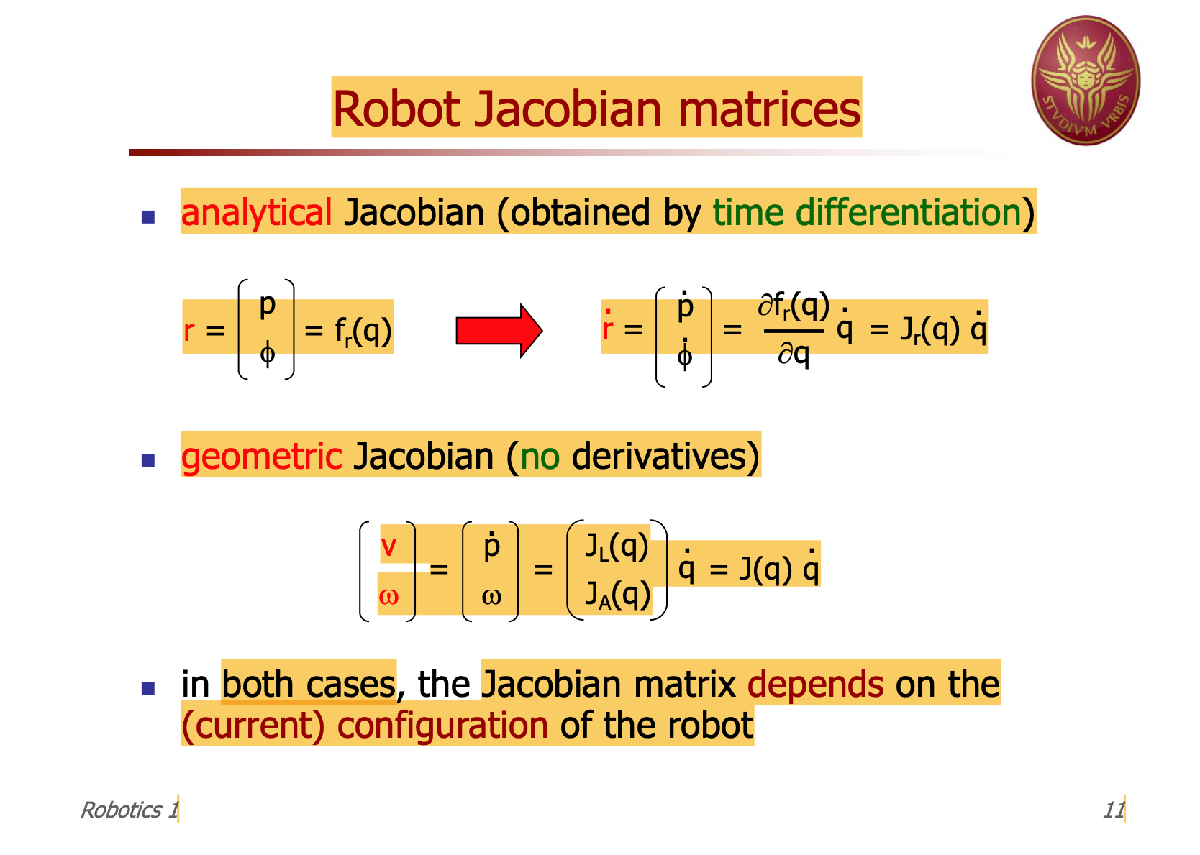

#### ANALYTICAL

syms alpha1 a1 d1 q1
syms alpha2 a2 d2 q2
syms alpha3 a3 d3 q3

disp('ANALYTICAL JACOBIAN ')

ANALYTICAL JACOBIAN 



disp('POLAR ROBOT (2R P)')

POLAR ROBOT (2R P)




% DH MODEL
%      alpha    a   d  theta
DH_table_ = ...
    [sym(-pi/2) 0  d1   q1;
     sym(pi/2)  0   0   q2;
        0       a3   0   q3];
    
SR_ROBO.showDHTable(DH_table_)

    joint_i     alpha_i      a_i       d_i      theta_i
    _______    _________    ______    ______    _______

       1       {'-pi/2'}    {'0' }    {'d1'}    {'q1'} 
       2       {'pi/2' }    {'0' }    {'0' }    {'q2'} 
       3       {'0'    }    {'a3'}    {'0' }    {'q3'} 




[T_sym, A_list_sym, type] = SR_ROBO.dh2dk(DH_table_,false);

type

type = 1×3 cell array
    {'r'}    {'r'}    {'r'}


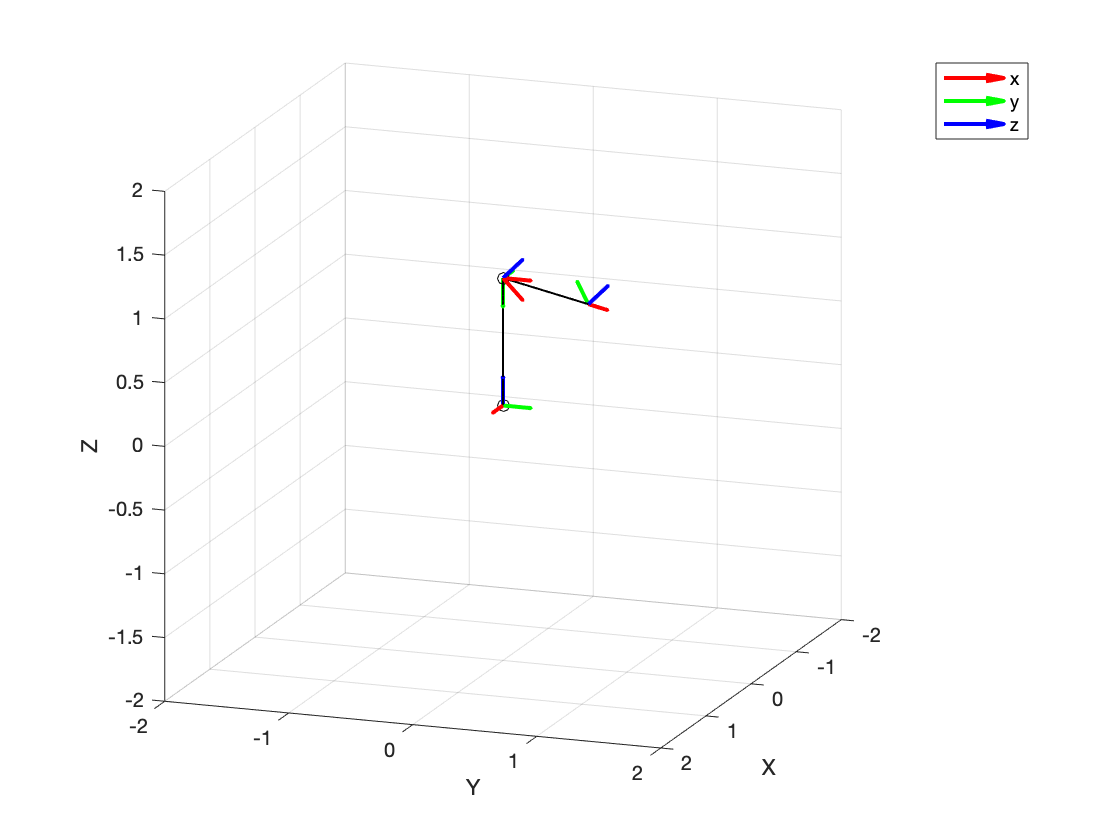


% DIRECT KINEMATIC
old = { d1,a3, q1, q2, q3};

new = { 1,1, pi/2, pi/4, 1};

A_list = cell(1,size(A_list_sym,1));

for i=1: length(A_list_sym)
    A_list{i} = double(subs(A_list_sym{i},old,new));
end

% PLOT ROBOT

SR_ROBO.draw(A_list,false);


F_sym = T_sym

$$F\_sym = \left(\begin{array}{cccc} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\sin\left(q_{1}\right)\,\sin\left(q_{3}\right) & -\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)-\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right) & \cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & a_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-a_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)\\ \cos\left(q_{1}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{3}\right)-\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & a_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)+a_{3}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\\ -\cos\left(q_{3}\right)\,\sin\left(q_{2}\right) & \sin\left(q_{2}\right)\,\sin\left(q_{3}\right) & \cos\left(q_{2}\right) & d_{1}-a_{3}\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% F_r(q) = (p phi)'

F_r = F_sym(1:3,4) % p

$$F\_r = \left(\begin{array}{c} a_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-a_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)\\ a_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)+a_{3}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\\ d_{1}-a_{3}\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right) \end{array}\right)$$


F_r(4)=q1+q2+q3 % q

$$F\_r = \left(\begin{array}{c} a_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-a_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)\\ a_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)+a_{3}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\\ d_{1}-a_{3}\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\\ q_{1}+q_{2}+q_{3} \end{array}\right)$$


J_r = jacobian(F_r,[q1 q2 q3])

$$J\_r = \left(\begin{array}{ccc} -a_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)-a_{3}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right) & -a_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right) & -a_{3}\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)-a_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ a_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-a_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right) & -a_{3}\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & a_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)-a_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)\\ 0 & -a_{3}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right) & a_{3}\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ 1 & 1 & 1 \end{array}\right)$$

#### GEOMETRICAL

syms q_dot_1 q_dot_2 q_dot_3

J = SR_ROBO.geometric_jacobian(DH_table_)

$$J = \left(\begin{array}{ccc} -a_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)-a_{3}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right) & -a_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right) & -a_{3}\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)-a_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ a_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-a_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right) & -a_{3}\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & a_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)-a_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)\\ 0 & -a_{3}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right) & a_{3}\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ 0 & -\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ 0 & \cos\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ 1 & 0 & \cos\left(q_{2}\right) \end{array}\right)$$


vel = J * [q_dot_1 q_dot_2 q_dot_3].';

[v0_E, w0_E] = deal(vel(1:3,:),vel(4:6,:))

$$v0\_E = \left(\begin{array}{c} -{\dot{q}}_{1}\,\left(a_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)+a_{3}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\right)-{\dot{q}}_{3}\,\left(a_{3}\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)+a_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)\right)-a_{3}\,{\dot{q}}_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\\ {\dot{q}}_{3}\,\left(a_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)-a_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)\right)-{\dot{q}}_{1}\,\left(a_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)-a_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\right)-a_{3}\,{\dot{q}}_{2}\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ a_{3}\,{\dot{q}}_{3}\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)-a_{3}\,{\dot{q}}_{2}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right) \end{array}\right)$$

$$w0\_E = \left(\begin{array}{c} {\dot{q}}_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)-{\dot{q}}_{2}\,\sin\left(q_{1}\right)\\ {\dot{q}}_{2}\,\cos\left(q_{1}\right)+{\dot{q}}_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ {\dot{q}}_{1}+{\dot{q}}_{3}\,\cos\left(q_{2}\right) \end{array}\right)$$


J_der = SR_ROBO.jacobian_derivative(J,[q1 q2 q3])

#### CHANGE REFERENCE FRAME

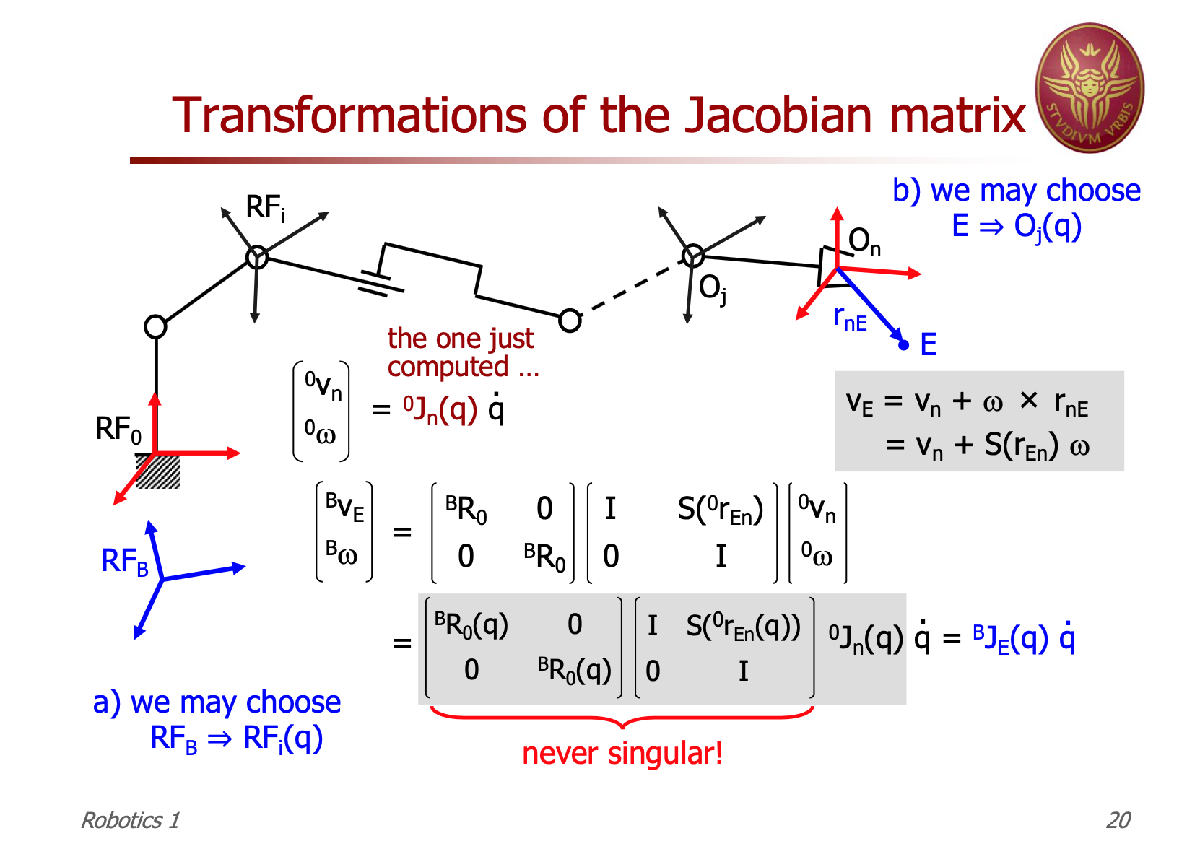

% assume whatever reference frame RB_0
RB_0 = [1 0 0; 
        0 1 0;
        0 0 1];
% determinant of the jacobian not depends by the reference frame
% compute r0_E
[T_sym, A_list_sym, type] = SR_ROBO.dh2dk(DH_table_,false);

r0_B = [0 0 0]'

r0_B =      0
     0
     0


r0_B = F_r 

$$r0\_B = \left(\begin{array}{c} a_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-a_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)\\ a_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)+a_{3}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\\ d_{1}-a_{3}\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\\ q_{1}+q_{2}+q_{3} \end{array}\right)$$

% -S_A_B because w_b x r_ab = - r_ab x w_b ==> v_a = v_b - r_ab x w_b 

S_0_B = -SR_ROBO.skew(r0_B(1),r0_B(2),r0_B(3))

$$S\_0\_B = \begin{array}{l} \left(\begin{array}{ccc} 0 & d_{1}-a_{3}\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right) & -a_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)-\sigma_{1}\\ a_{3}\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)-d_{1} & 0 & \sigma_{2}-a_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)\\ a_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)+\sigma_{1} & a_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)-\sigma_{2} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{3}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\\ \sigma_{2}=a_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right) \end{array}$$


vel_B = simplify([RB_0 zeros(3,3); zeros(3,3) RB_0] * [eye(3,3) S_0_B; zeros(3,3) eye(3,3)] * [v0_E; w0_E])

$$vel\_B = \left(\begin{array}{c} d_{1}\,{\dot{q}}_{2}\,\cos\left(q_{1}\right)-2\,a_{3}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)-2\,a_{3}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)+d_{1}\,{\dot{q}}_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)-2\,a_{3}\,{\dot{q}}_{1}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)-2\,a_{3}\,{\dot{q}}_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)-2\,a_{3}\,{\dot{q}}_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ d_{1}\,{\dot{q}}_{2}\,\sin\left(q_{1}\right)+2\,a_{3}\,{\dot{q}}_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)-d_{1}\,{\dot{q}}_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)-2\,a_{3}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)+2\,a_{3}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-2\,a_{3}\,{\dot{q}}_{2}\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)-2\,a_{3}\,{\dot{q}}_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)\\ 2\,a_{3}\,{\dot{q}}_{3}\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)-2\,a_{3}\,{\dot{q}}_{2}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\\ {\dot{q}}_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)-{\dot{q}}_{2}\,\sin\left(q_{1}\right)\\ {\dot{q}}_{2}\,\cos\left(q_{1}\right)+{\dot{q}}_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ {\dot{q}}_{1}+{\dot{q}}_{3}\,\cos\left(q_{2}\right) \end{array}\right)$$


[vB_E, wB_E] = deal(vel_B(1:3,:),vel_B(4:6,:))

$$vB\_E = \left(\begin{array}{c} d_{1}\,{\dot{q}}_{2}\,\cos\left(q_{1}\right)-2\,a_{3}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)-2\,a_{3}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)+d_{1}\,{\dot{q}}_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)-2\,a_{3}\,{\dot{q}}_{1}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)-2\,a_{3}\,{\dot{q}}_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)-2\,a_{3}\,{\dot{q}}_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ d_{1}\,{\dot{q}}_{2}\,\sin\left(q_{1}\right)+2\,a_{3}\,{\dot{q}}_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)-d_{1}\,{\dot{q}}_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)-2\,a_{3}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)+2\,a_{3}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-2\,a_{3}\,{\dot{q}}_{2}\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)-2\,a_{3}\,{\dot{q}}_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)\\ 2\,a_{3}\,{\dot{q}}_{3}\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)-2\,a_{3}\,{\dot{q}}_{2}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right) \end{array}\right)$$

$$wB\_E = \left(\begin{array}{c} {\dot{q}}_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)-{\dot{q}}_{2}\,\sin\left(q_{1}\right)\\ {\dot{q}}_{2}\,\cos\left(q_{1}\right)+{\dot{q}}_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ {\dot{q}}_{1}+{\dot{q}}_{3}\,\cos\left(q_{2}\right) \end{array}\right)$$


% THIS MAY SIMPLIFY THE EXPRESSION OF THE JACOBIAN

# SUMMARY 

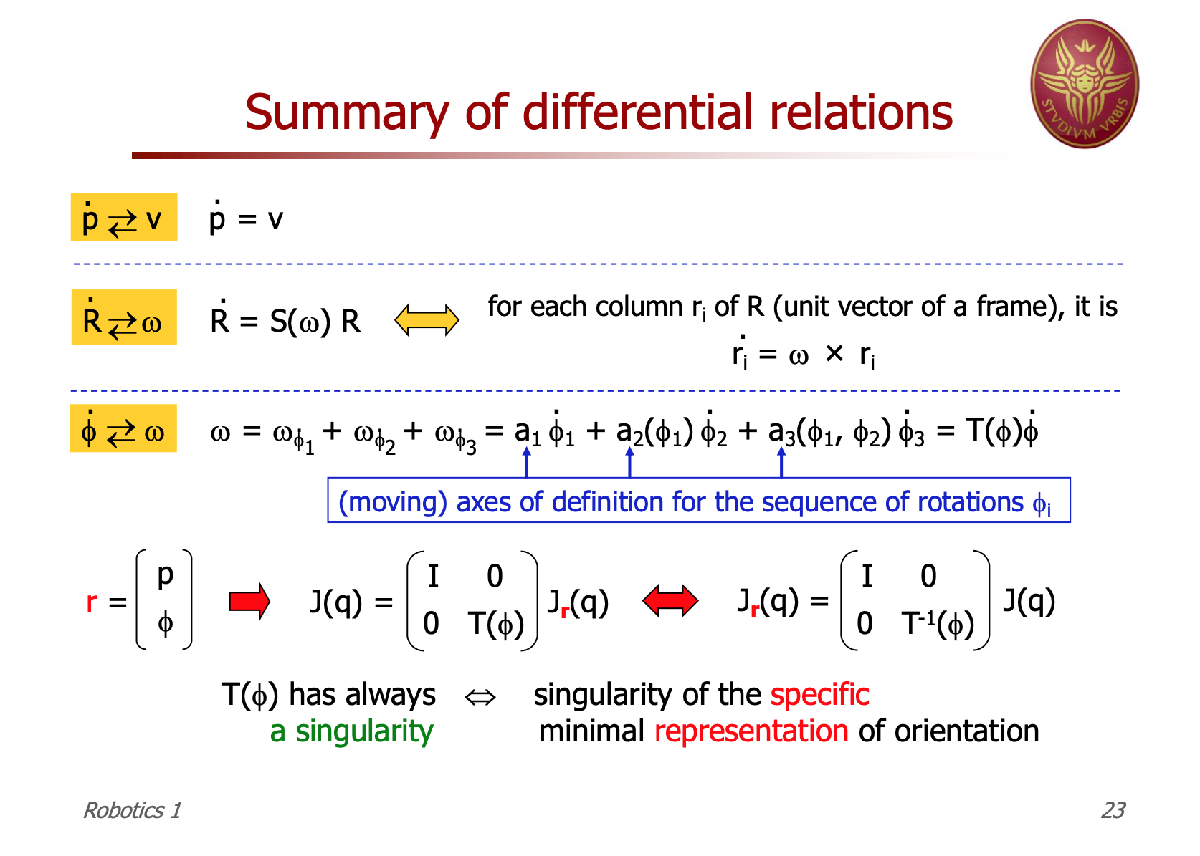

% if taking as task vector r = (p phi)'
% suppose orientation of end frame expressed in RPY (fixed) = ZYX (moving)

T = SR_ROBO.getMappingT(q3,q2,q1,'zyx')

$$T = \left(\begin{array}{ccc} 0 & -\sin\left(q_{3}\right) & \cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\\ 0 & \cos\left(q_{3}\right) & \cos\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ 1 & 0 & -\sin\left(q_{2}\right) \end{array}\right)$$


% antropomorphic arm
DH_table_ = ...
    [sym(pi/2)  0  d1   q1;
        0       a2  0   q2;
        0       a3  0   q3];
    
SR_ROBO.showDHTable(DH_table_)

    joint_i    alpha_i      a_i       d_i      theta_i
    _______    ________    ______    ______    _______

       1       {'pi/2'}    {'0' }    {'d1'}    {'q1'} 
       2       {'0'   }    {'a2'}    {'0' }    {'q2'} 
       3       {'0'   }    {'a3'}    {'0' }    {'q3'} 




[T_sym, A_list_sym, type] = SR_ROBO.dh2dk(DH_table_,false);

F_r = T_sym(1:3,4) % p

$$F\_r = \left(\begin{array}{c} a_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)+a_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-a_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ a_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)+a_{3}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)-a_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ d_{1}+a_{2}\,\sin\left(q_{2}\right)+a_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+a_{3}\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right) \end{array}\right)$$


J = SR_ROBO.geometric_jacobian(DH_table_)

$$J = \begin{array}{l} \left(\begin{array}{ccc} -\sin\left(q_{1}\right)\,\sigma_{1} & -\cos\left(q_{1}\right)\,\sigma_{2} & -a_{3}\,\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\\ \cos\left(q_{1}\right)\,\sigma_{1} & -\sin\left(q_{1}\right)\,\sigma_{2} & -a_{3}\,\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)\\ 0 & \sigma_{1} & a_{3}\,\cos\left(q_{2}+q_{3}\right)\\ 0 & \sin\left(q_{1}\right) & \sin\left(q_{1}\right)\\ 0 & -\cos\left(q_{1}\right) & -\cos\left(q_{1}\right)\\ 1 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{3}\,\cos\left(q_{2}+q_{3}\right)+a_{2}\,\cos\left(q_{2}\right)\\ \sigma_{2}=a_{3}\,\sin\left(q_{2}+q_{3}\right)+a_{2}\,\sin\left(q_{2}\right) \end{array}$$


J_r = simplify([eye(3,3) zeros(3,3); zeros(3,3) inv(T)] * J)

$$J\_r = \begin{array}{l} \left(\begin{array}{ccc} -\sin\left(q_{1}\right)\,\sigma_{1} & -\cos\left(q_{1}\right)\,\sigma_{2} & -a_{3}\,\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\\ \cos\left(q_{1}\right)\,\sigma_{1} & -\sin\left(q_{1}\right)\,\sigma_{2} & -a_{3}\,\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)\\ 0 & \sigma_{1} & a_{3}\,\cos\left(q_{2}+q_{3}\right)\\ 1 & \sigma_{3} & \sigma_{3}\\ 0 & -\cos\left(q_{1}-q_{3}\right) & -\cos\left(q_{1}-q_{3}\right)\\ 0 & \sigma_{4} & \sigma_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{3}\,\cos\left(q_{2}+q_{3}\right)+a_{2}\,\cos\left(q_{2}\right)\\ \sigma_{2}=a_{3}\,\sin\left(q_{2}+q_{3}\right)+a_{2}\,\sin\left(q_{2}\right)\\ \sigma_{3}=\frac{\sin\left(q_{1}-q_{3}\right)\,\sin\left(q_{2}\right)}{\cos\left(q_{2}\right)}\\ \sigma_{4}=\frac{\sin\left(q_{1}-q_{3}\right)}{\cos\left(q_{2}\right)} \end{array}$$

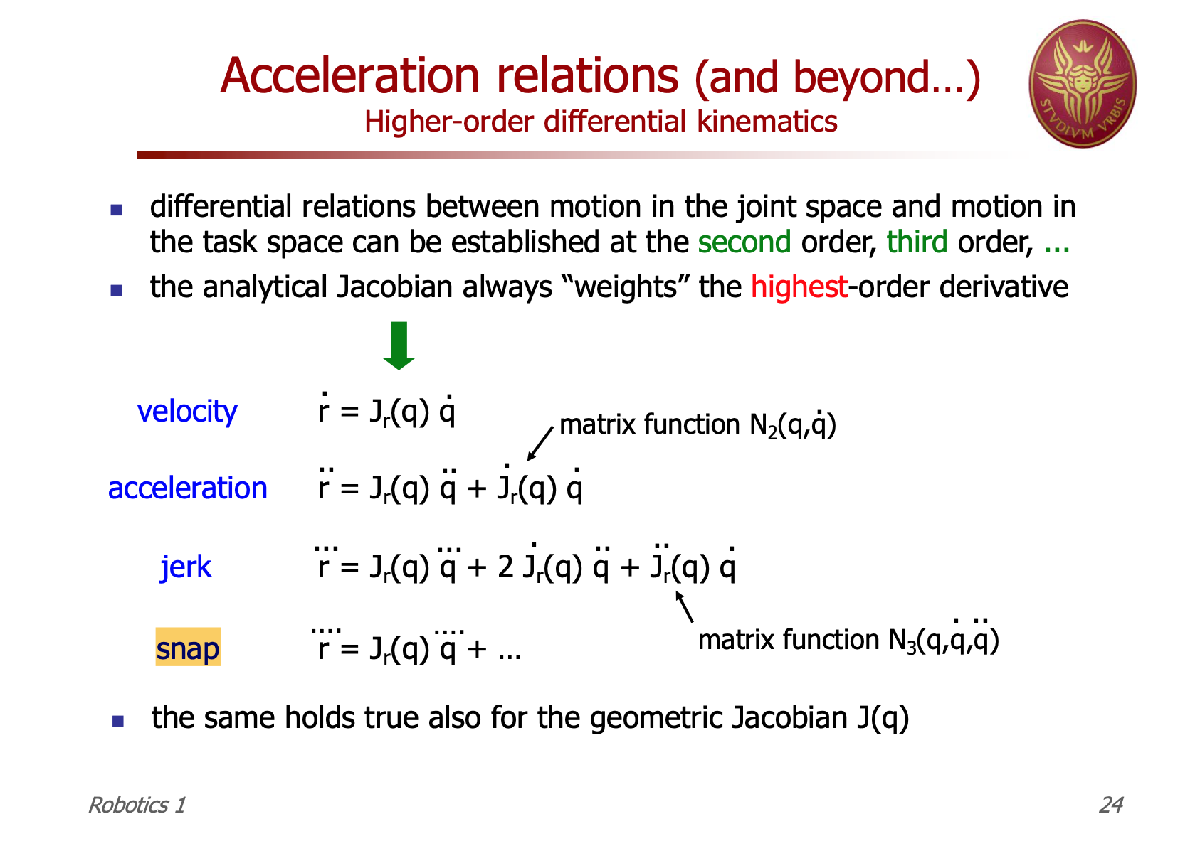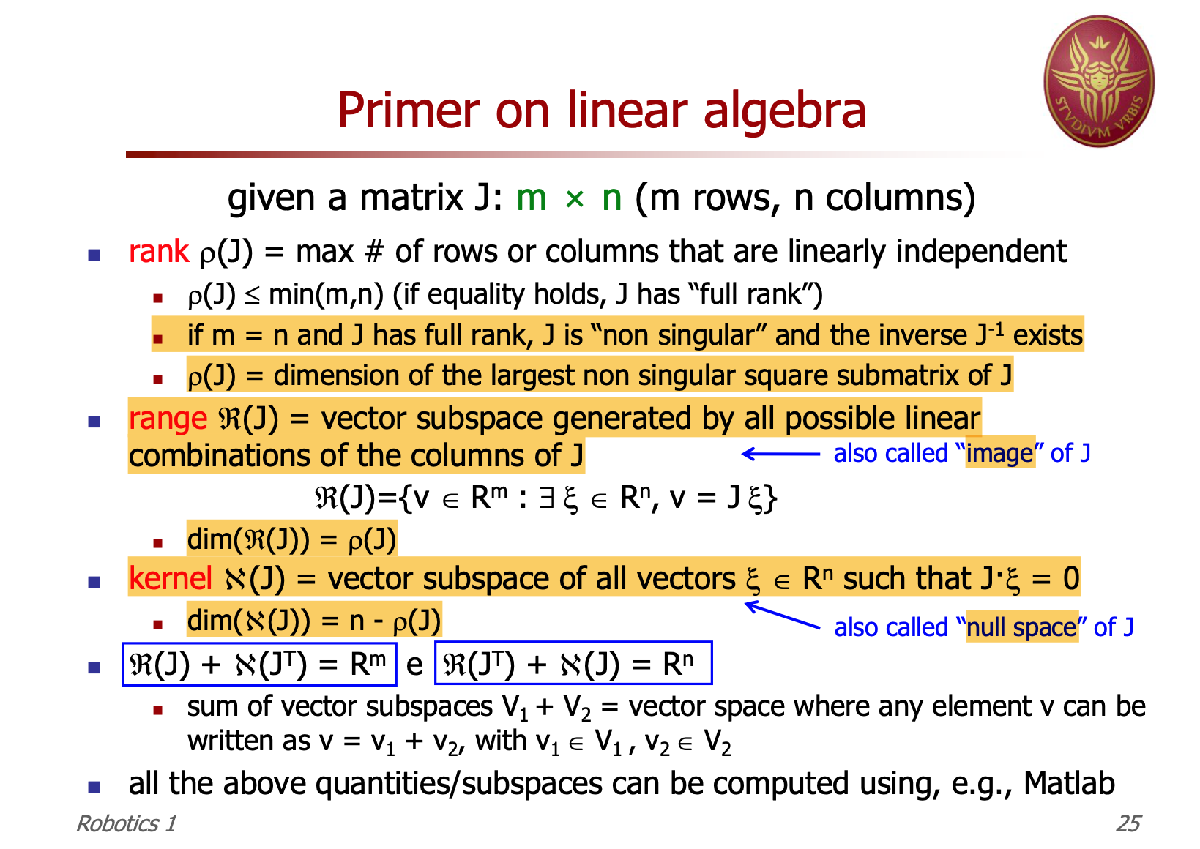

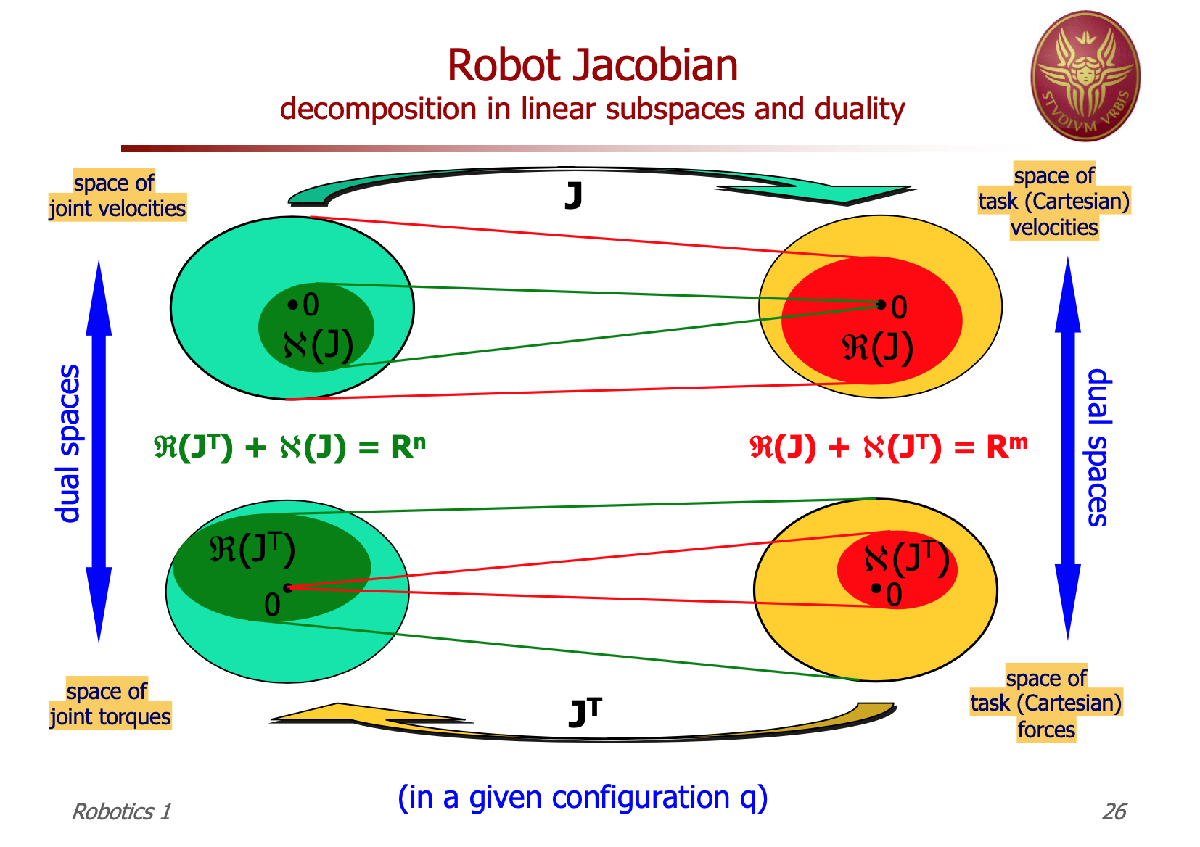

# ANTROPOMORPHIC ARM SUBSPACES

disp('ANTROPOMORPHIC ARM SUBSPACES')

ANTROPOMORPHIC ARM SUBSPACES


DH_table_ = ...
    [sym(pi/2)  0  d1   q1;
        0       a2  0   q2;
        0       a3  0   q3];
    
SR_ROBO.showDHTable(DH_table_)

    joint_i    alpha_i      a_i       d_i      theta_i
    _______    ________    ______    ______    _______

       1       {'pi/2'}    {'0' }    {'d1'}    {'q1'} 
       2       {'0'   }    {'a2'}    {'0' }    {'q2'} 
       3       {'0'   }    {'a3'}    {'0' }    {'q3'} 



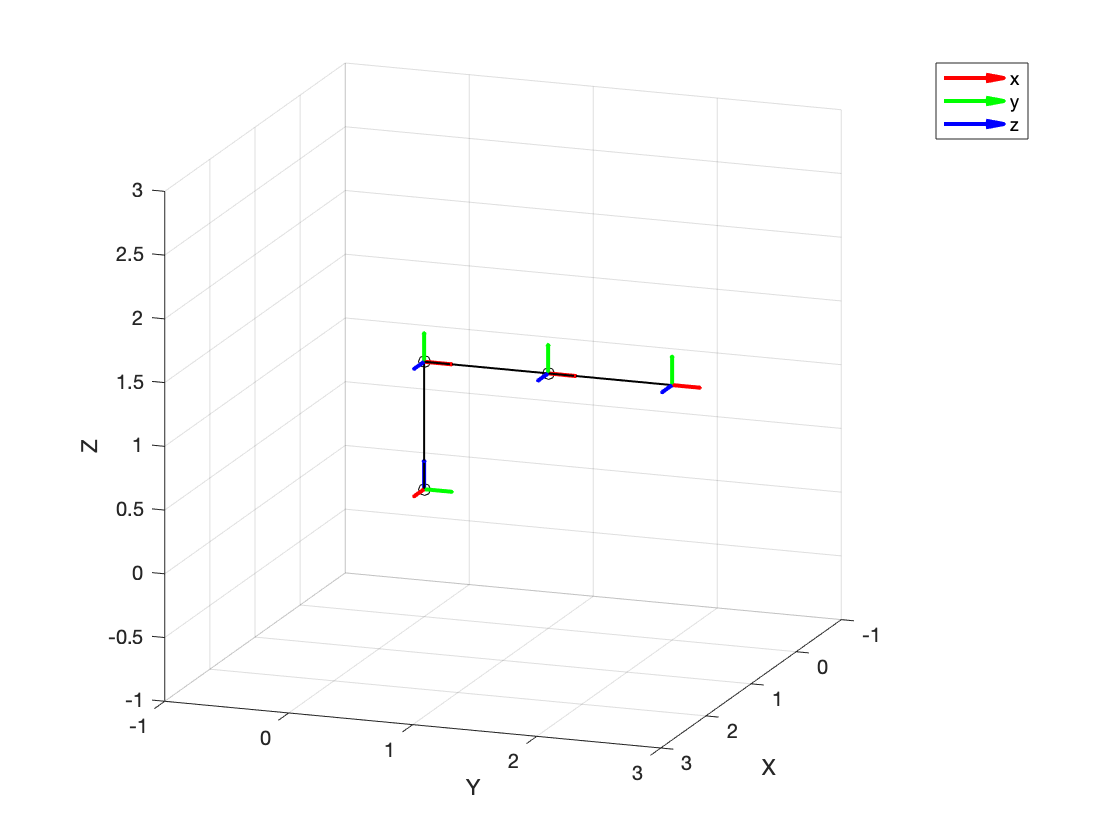


[T_sym, A_list_sym, type] = SR_ROBO.dh2dk(DH_table_,false);

old = { d1, a2, a3, q1, q2, q3};

new = { 1, 1, 1, pi/2, 0, 0}; % singular configuration, try {pi/2, pi/4, -pi/2} instead

A_list = cell(1,size(A_list_sym,1));

for i=1: length(A_list_sym)
    A_list{i} = double(subs(A_list_sym{i},old,new));
end

% PLOT ROBOT
SR_ROBO.draw(A_list,false);



F_r = T_sym(1:3,4) % p

$$F\_r = \left(\begin{array}{c} a_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)+a_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-a_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ a_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)+a_{3}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)-a_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ d_{1}+a_{2}\,\sin\left(q_{2}\right)+a_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+a_{3}\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right) \end{array}\right)$$


J = simplify(jacobian(F_r,[q1 q2 q3]))

$$J = \begin{array}{l} \left(\begin{array}{ccc} -\sin\left(q_{1}\right)\,\sigma_{1} & -\cos\left(q_{1}\right)\,\sigma_{2} & -a_{3}\,\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\\ \cos\left(q_{1}\right)\,\sigma_{1} & -\sin\left(q_{1}\right)\,\sigma_{2} & -a_{3}\,\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)\\ 0 & \sigma_{1} & a_{3}\,\cos\left(q_{2}+q_{3}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{3}\,\cos\left(q_{2}+q_{3}\right)+a_{2}\,\cos\left(q_{2}\right)\\ \sigma_{2}=a_{3}\,\sin\left(q_{2}+q_{3}\right)+a_{2}\,\sin\left(q_{2}\right) \end{array}$$


J = subs(J,old,new) 

$$J = \left(\begin{array}{ccc} -2 & 0 & 0\\ 0 & 0 & 0\\ 0 & 2 & 1 \end{array}\right)$$


rank_J = rank(J)

rank_J = 2


nullspace_J = null(J)

$$nullspace\_J = \left(\begin{array}{c} 0\\ -\frac{1}{2}\\ 1 \end{array}\right)$$


null_J = size(nullspace_J,2)

null_J = 1


JT = J'

$$JT = \left(\begin{array}{ccc} -2 & 0 & 0\\ 0 & 0 & 2\\ 0 & 0 & 1 \end{array}\right)$$


rank_JT = rank(JT)

rank_JT = 2


nullspace_JT = null(JT)

$$nullspace\_JT = \left(\begin{array}{c} 0\\ 1\\ 0 \end{array}\right)$$


null_JT = size(nullspace_JT,2)

null_JT = 1


R_n = rank_JT + null_J

R_n = 3


R_m = rank_J + null_JT

R_m = 3

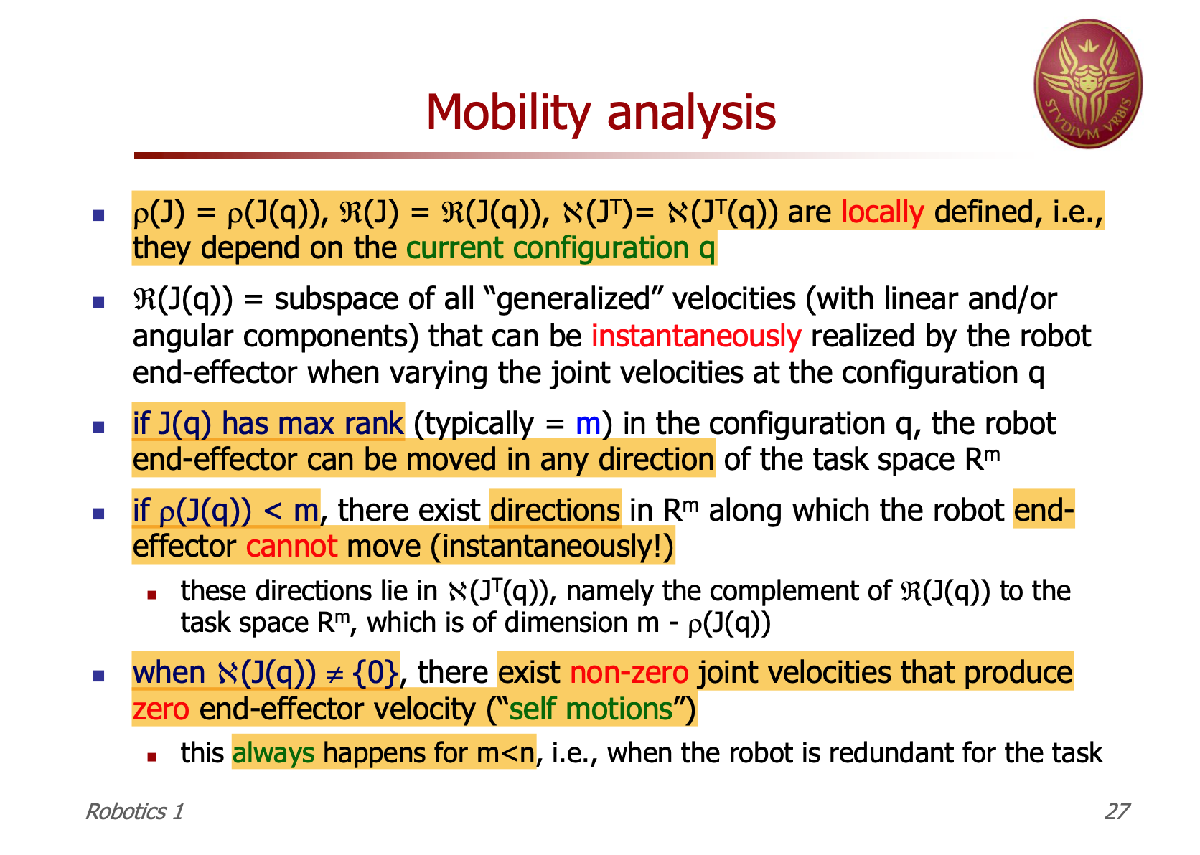

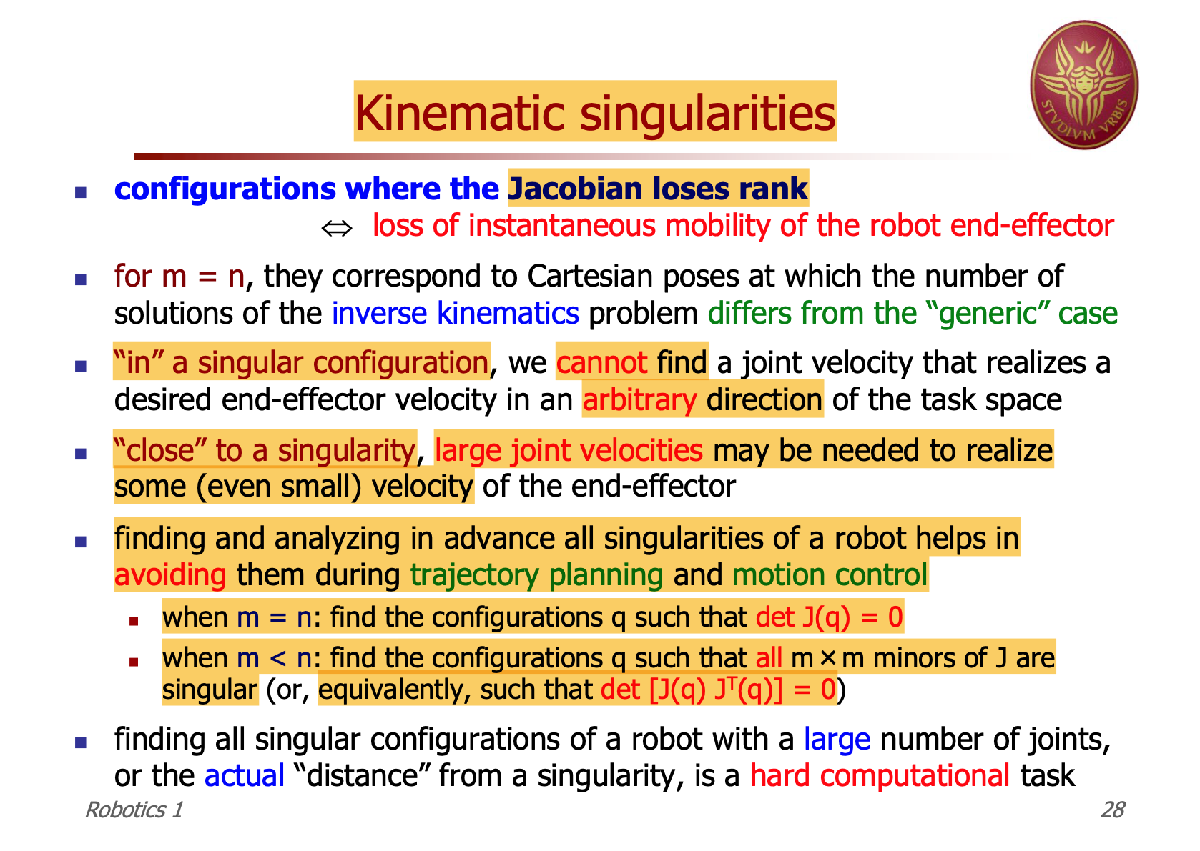

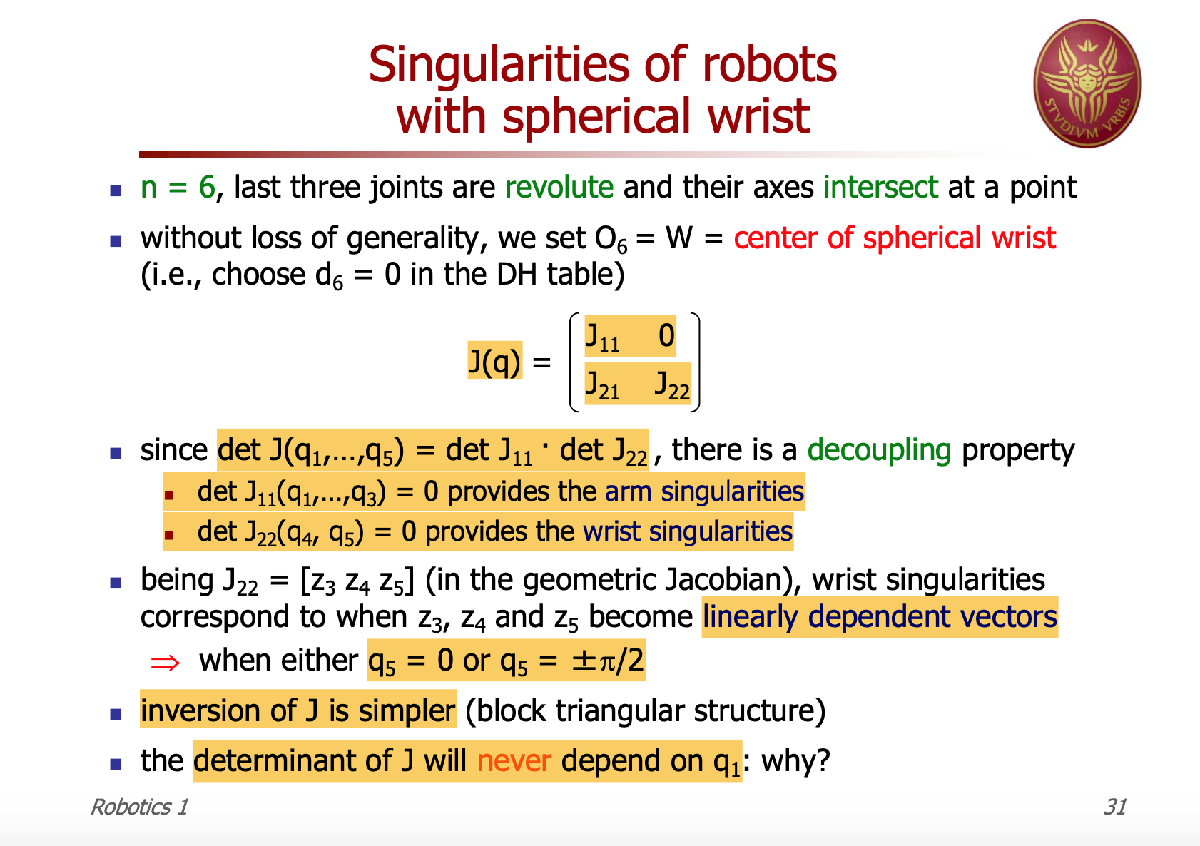

syms alpha4 a4 d4 q4
syms alpha5 a5 d5 q5
syms alpha6 a6 d6 q6

disp('ANTROPOMORPHIC ARM WITH SPHERICAL WRIST SINGULARITIES')

ANTROPOMORPHIC ARM WITH SPHERICAL WRIST SINGULARITIES



DH_table_arm = ...
    [sym(pi/2)  0   0   q1;
        0       a2  0   q2;
     sym(pi/2)  0   0   q3];
 
DH_table_wrist = ...
   [sym(-pi/2)  0  d4  q4;
    sym(pi/2)   0  0   q5;
       0        0  0   q6];
   %d6=0 to have simpler expression
DH_table_ = [DH_table_arm; DH_table_wrist];
    
SR_ROBO.showDHTable(DH_table_)

    joint_i     alpha_i      a_i       d_i      theta_i
    _______    _________    ______    ______    _______

       1       {'pi/2' }    {'0' }    {'0' }    {'q1'} 
       2       {'0'    }    {'a2'}    {'0' }    {'q2'} 
       3       {'pi/2' }    {'0' }    {'0' }    {'q3'} 
       4       {'-pi/2'}    {'0' }    {'d4'}    {'q4'} 
       5       {'pi/2' }    {'0' }    {'0' }    {'q5'} 
       6       {'0'    }    {'0' }    {'0' }    {'q6'} 



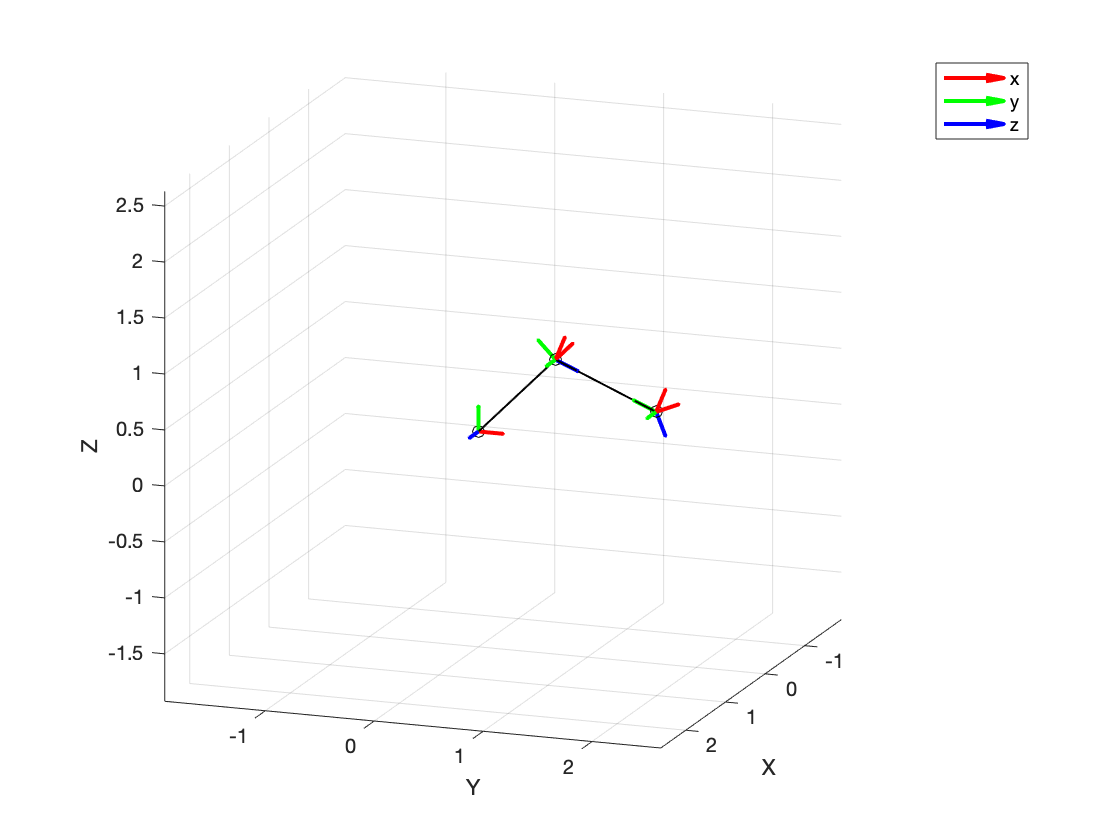


[T_sym, A_list_sym, type] = SR_ROBO.dh2dk(DH_table_,false);

old = { a2, d4, q1, q2, q3, q4, q5, q6};

new = { 1, 1, pi/2, pi/4, pi/8, 0, -pi/4, 0};

A_list = cell(1,size(A_list_sym,1));

for i=1: length(A_list_sym)
    A_list{i} = double(subs(A_list_sym{i},old,new));
end

% PLOT ROBOT
SR_ROBO.draw(A_list,false);


J = simplify(SR_ROBO.geometric_jacobian(DH_table_))